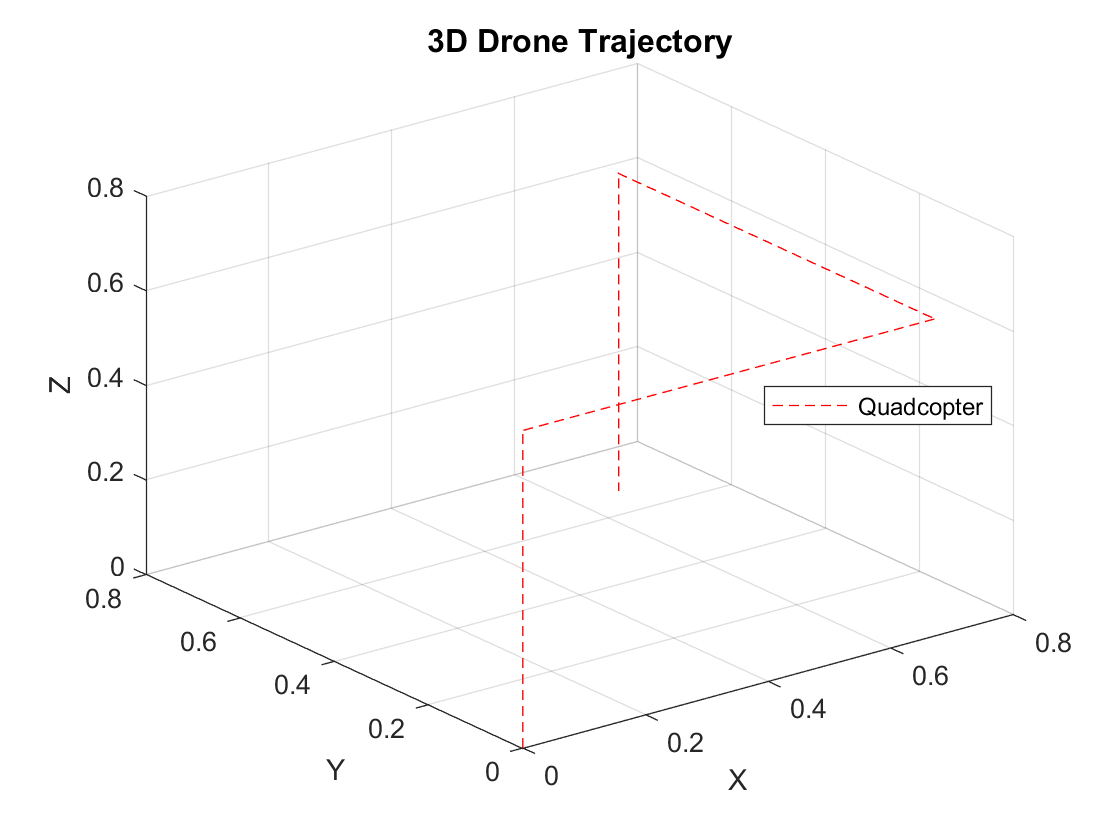

t = 0;
dt = 0.070707070707071;
acc = [0;0;0];
vel = [0;0;0];
pos = [0;0;0];

result = [];
check = [];
check_taub_2 = [];

q = [0;0;0];
qdot = [0;0;0];
qdot = [0;0;0];

b = 1.14*10^-7;
%{
m0 = .154;
m = [.05 0 0 0];
mtot = mass(m0, m);
%}
p = [.07071 0 -.07071 0;
    0 .07071 0 -.07071;
    .03076 .03076 .03076 .03076];
 
p_cmx = pcmx( m, p );
p_cmy = pcmy( m, p );
p_cmz = pcmz( m, p );

l = link( p, p_cmx, p_cmy, p_cmz );

g = 9.81;
G = grav(mtot,g);

A = eye(3); %kg/s %mass air flow?
A = 0.25*A; 
    
Ixx = 4.856*10^-3;
Iyy = 4.856*10^-3;
Izz = 8.801*10^-3;
I = [Ixx; Iyy; Izz]; %m^2/kg
I = diag(I); %inertial values  
     
for i = 1:400

    w = [solution_2(i,1);solution_2(i,2);solution_2(i,3);solution_2(i,4)];   
    k = [0.00000000571683;0.00000000571683;0.00000000571683;0.00000000571683];
    
    f = eff(k, w);
    Tb = thrustquad2(f);
    if i == 200
        test=0;
    end
    tau_m = b*(w(1)-w(2)+w(3)-w(4));
    if tau_m  <= 0.000001
        tau_m = 0;
    end
    tau_b = taub( l, k, w, tau_m ); 
    
    check_taub_2 = [check_taub_2,tau_b];
    
    W_eta = [1, 0, -sin(q(2));
        0, cos(q(1)), cos(q(2))*sin(q(1));
        0, -sin(q(1)), cos(q(2))*cos(q(1))];
    J = transpose(W_eta)*I*W_eta;
    
    C11 = 0;
    C12 = (Iyy - Izz)*(qdot(2)*cos(q(1))*sin(q(1)) + qdot(3)*((sin(q(1)))^2)*cos(q(2))) + (Izz - Iyy)*qdot(3)*((cos(q(1)))^2)*cos(q(2)) - Ixx*qdot(3)*cos(q(2));
    C13 = (Izz - Iyy)*qdot(3)*((cos(q(2)))^2)*cos(q(1))*sin(q(1));
    C21 = (Izz - Iyy)*(qdot(2)*cos(q(1))*sin(q(1)) + qdot(3)*((sin(q(1)))^2)*cos(q(2))) + (Iyy - Izz)*qdot(3)*((cos(q(1)))^2)*cos(q(2)) + Ixx*qdot(3)*cos(q(2));
    C22 = (Izz - Iyy)*qdot(1)*cos(q(1))*sin(q(1));
    C23 = -Ixx*qdot(3)*sin(q(2))*cos(q(2)) + Iyy*qdot(3)*((sin(q(1)))^2)*sin(q(2))*cos(q(2)) + Izz*qdot(3)*((cos(q(1)))^2)*sin(q(2))*cos(q(2));
    C31 = (Iyy - Izz)*qdot(3)*((cos(q(2)))^2)*cos(q(1))*sin(q(1)) - Ixx*qdot(2)*cos(q(2));
    C32 = (Izz - Iyy)*(qdot(2)*cos(q(1))*sin(q(1))*sin(q(2)) + qdot(1)*((sin(q(1)))^2)*cos(q(2))) + (Iyy - Izz)*qdot(1)*((cos(q(1)))^2)*cos(q(2)) + Ixx*qdot(3)*sin(q(2))*cos(q(2)) - Iyy*qdot(3)*((sin(q(1)))^2)*sin(q(2))*cos(q(2)) - Izz*qdot(3)*((cos(q(1)))^2)*sin(q(2))*cos(q(2));
    C33 = (Iyy - Izz)*qdot(1)*((cos(q(2)))^2)*sin(q(1))*cos(q(1)) - Iyy*qdot(2)*((sin(q(1)))^2)*sin(q(2))*cos(q(2)) - Izz*qdot(2)*((cos(q(1)))^2)*sin(q(2))*cos(q(2)) + Ixx*qdot(2)*sin(q(2))*cos(q(2));
    
    C = [C11 C12 C13;C21 C22 C23;C31 C32 C33];
    
    qddot = etaddot( tau_b, C, J, qdot);
    qdot = etadot( dt, qddot, qdot);
    q = eta( dt, qdot, q);
    
    check = [check,q];
    
    Rz = [cos(q(3)) -sin(q(3)) 0;sin(q(3)) cos(q(3)) 0;0 0 1];
    Ry = [cos(q(2)) 0 sin(q(2));0 1 0;-sin(q(2)) 0 cos(q(2))];
    Rx = [1 0 0;0 cos(q(1)) -sin(q(1));0 sin(q(1)) cos(q(1))];
    
    R = Rz*Ry*Rx;

    acc = (G+R*Tb-A*vel)/mtot;
    vel = vel + dt*acc;
    pos = pos + dt*vel;
    
    if pos(3) <= 0 
        pos(3) = 0;
    end
               
    time(i,1) = t;
    result(i,1) = pos(1);
    result(i,2) = pos(2);
    result(i,3) = pos(3);
    result(i,4) = vel(1);
    result(i,5) = vel(2);
    result(i,6) = vel(3);
    result(i,7) = acc(1);
    result(i,8) = acc(2);
    result(i,9) = acc(3);
    result(i,10) = q(1);
    result(i,11) = q(2);
    result(i,12) = q(3);
    result(i,13) = qdot(1);
    result(i,14) = qdot(2);
    result(i,15) = qdot(3);
    result(i,16) = qddot(1);
    result(i,17) = qddot(2);
    result(i,18) = qddot(3);
    t = t + dt;
end

th = transpose(th);
phi = transpose(phi);
psi = 0;

for i = 1:400
    pause(.0001)
    figure(6);
    plot3(result(1:i,1),result(1:i,2), result(1:i,3),'r--')
    title('3D Drone Trajectory', 'FontSize', 12);
    xlabel('X'); ylabel('Y'); zlabel('Z');
    legend({'Quadcopter'},'Location','east');
    grid on;
    xlim([0 0.8]);
    ylim([0 0.8]);
    zlim([0 0.8]);
end

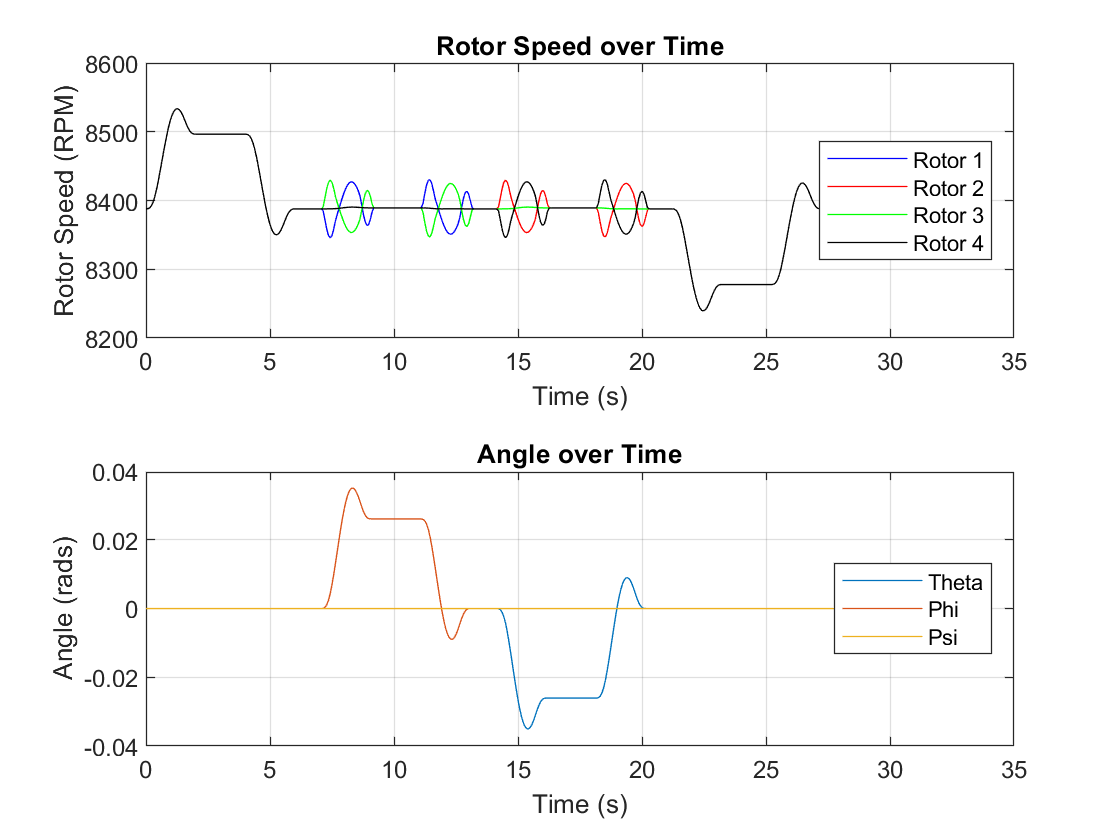


figure(1);
tiledlayout(2,1)
nexttile;
plot(time,solution_2(:,1),'b',time,solution_2(:,2),'r',time, solution_2(:,3),'g',time,solution_2(:,4),'k')
title('Rotor Speed over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('Rotor Speed (RPM)'); zlabel('Z');
legend({'Rotor 1','Rotor 2','Rotor 3','Rotor 4'},'Location','east');
grid on;
%ylim([7950 8300]);
xlim([0 35]);

nexttile;
plot(time,result(:,10),time,result(:,11),time,result(:,12))
title('Angle over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('Angle (rads)'); zlabel('Z');
legend({'Theta','Phi','Psi'},'Location','east');
grid on;
ylim([-0.04 0.04]);
xlim([0 35]);

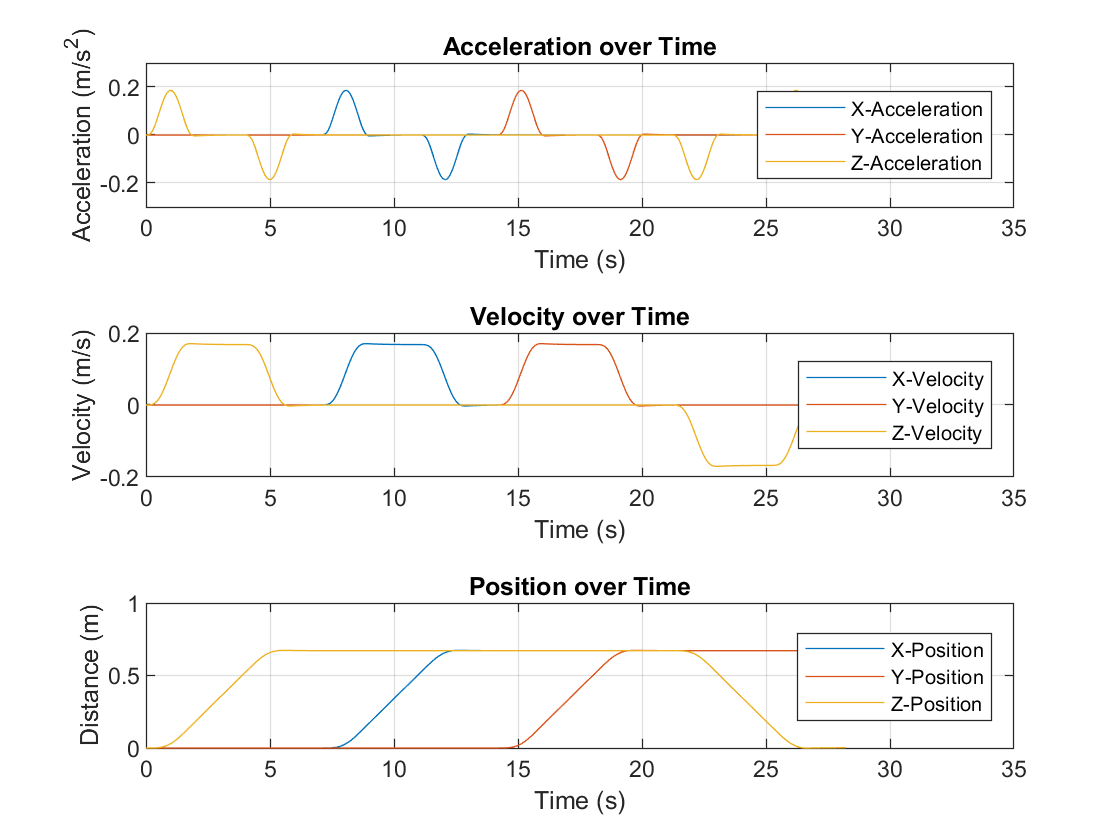


figure(2)
tiledlayout(3,1)
nexttile;
plot(time,result(:,7),time,result(:,8),time, result(:,9))
title('Acceleration over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('Acceleration (m/s^2)'); zlabel('Z');
legend({'X-Acceleration','Y-Acceleration','Z-Acceleration'},'Location','east');
grid on;
xlim([0 35]);
ylim([-0.3 .3]);

nexttile;
plot(time,result(:,4),time,result(:,5),time, result(:,6))
title('Velocity over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('Velocity (m/s)'); zlabel('Z');
legend({'X-Velocity','Y-Velocity','Z-Velocity'},'Location','east');
grid on;
xlim([0 35]);

nexttile;
plot(time,result(:,1),time,result(:,2),time, result(:,3))
title('Position over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('Distance (m)'); zlabel('Z');
legend({'X-Position','Y-Position','Z-Position'},'Location','east');
grid on;
xlim([0 35]);
ylim([0 1]);

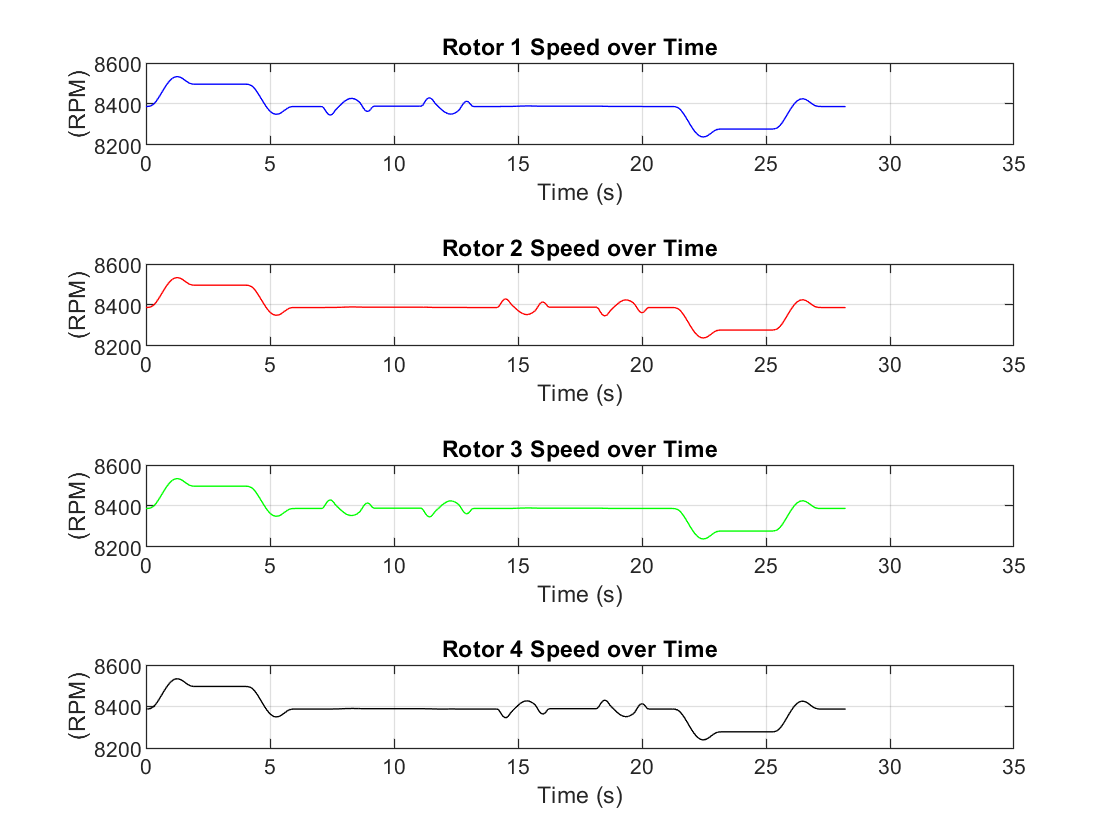

figure(3)
tiledlayout(4,1)
nexttile;
plot(time,solution_2(:,1),'b')
title('Rotor 1 Speed over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('(RPM)'); zlabel('Z');
%legend({'Rotor 1','Rotor 2','Rotor 3','Rotor 4'},'Location','east');
grid on;
%ylim([7950 8300]);
xlim([0 35]);

nexttile;
plot(time,solution_2(:,2),'r')
title('Rotor 2 Speed over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('(RPM)'); zlabel('Z');
%legend({'Rotor 1','Rotor 2','Rotor 3','Rotor 4'},'Location','east');
grid on;
%ylim([7950 8300]);
xlim([0 35]);

nexttile;
plot(time,solution_2(:,3),'g')
title('Rotor 3 Speed over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('(RPM)'); zlabel('Z');
%legend({'Rotor 1','Rotor 2','Rotor 3','Rotor 4'},'Location','east');
grid on;
%ylim([7950 8300]);
xlim([0 35]);

nexttile;
plot(time,solution_2(:,4),'k')
title('Rotor 4 Speed over Time', 'FontSize', 12);
xlabel('Time (s)'); ylabel('(RPM)'); zlabel('Z');
%legend({'Rotor 1','Rotor 2','Rotor 3','Rotor 4'},'Location','east');
grid on;
%ylim([7950 8300]);
xlim([0 35]);